Mostrando tabla de: barrido_J
    Modelo     Motor    J_factor     J_var        fe_Hz      THD_Ia_pct    THD_Ib_pct     Te_mean      Te_ripple_rms    Te_ripple_pp     Wm_mean      Wm_ripple_pp    error_theta_deg       error_Wm   
    _______    _____    ________    ________    _________    __________    __________    __________    _____________    ____________    __________    ____________    _______________    ______________

    "Jx0.5"    "M0"       0.5       2.35e-06       359.55      18.822        18.822      4.52

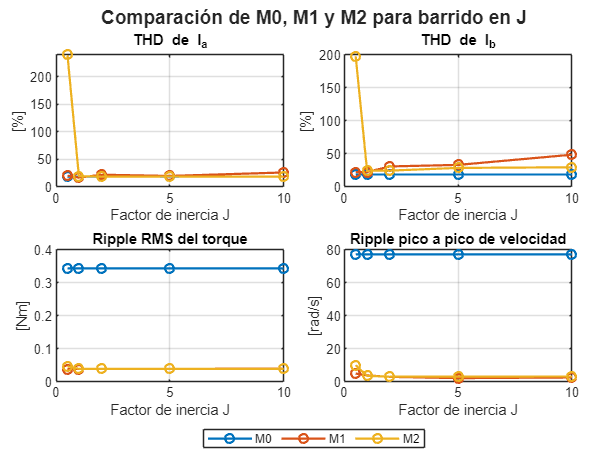

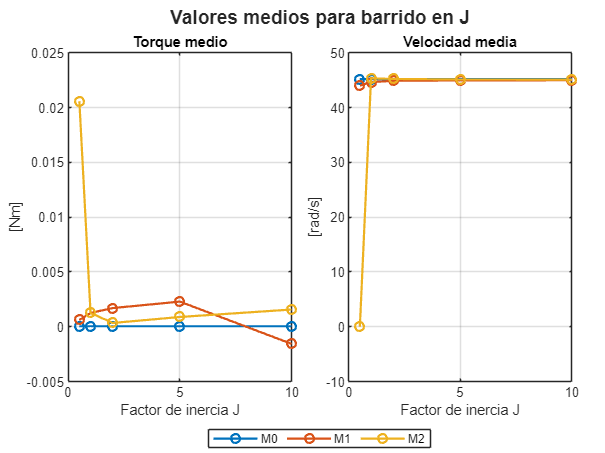

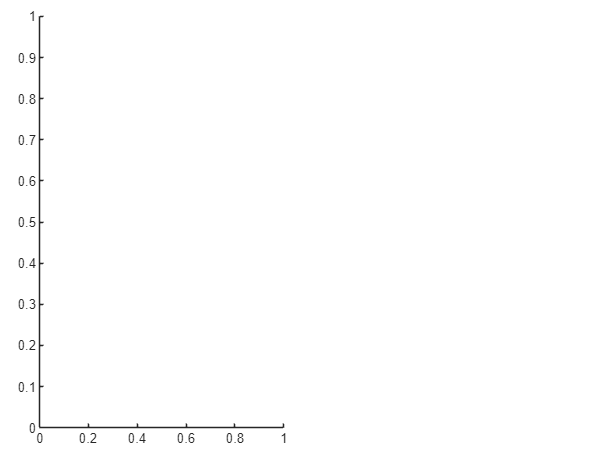

Incorrect number or types of inputs or outputs for function isnan.

Error in graficas>graficarUnaMetrica (line 187)
        idxValid = ~(isnan(x) | isnan(y) | isinf(x) | isinf(y));

Error in graficas>graficarComparacionMotores (line 135)
        graficarUnaMetrica(summaryTable, motorNames, sortVar, "error_theta_deg");

clc
close all
clear

graficarComparacionMotores("barrido_J", "J_factor");

graficarComparacionMotores("barrido_B", "B_factor");

function graficarComparacionMotores(rootFolder, sortVar)

    summaryFile = fullfile(rootFolder, "summaryTable.mat");
    S = load(summaryFile);
    summaryTable = S.summaryTable;

    disp("Mostrando tabla de: " + rootFolder)
    disp(summaryTable)

    % Robustez con tipos de texto
    summaryTable.Motor = string(summaryTable.Motor);
    summaryTable.Modelo = string(summaryTable.Modelo);

    motorNames = unique(summaryTable.Motor, 'stable');

    % Etiqueta bonita para eje X
    if sortVar == "J_factor"
        xLabelTxt = "Factor de inercia J";
    elseif sortVar == "B_factor"
        xLabelTxt = "Factor de fricción B";
    else
        xLabelTxt = strrep(char(sortVar), '_', '\_');
    end

    %% =========================
    %% Figura resumen dinámica
    %% =========================
    fig1 = figure('Name', "Comparación motores - " + rootFolder, ...
                  'Color', 'w');
    tl1 = tiledlayout(2,2, 'Padding', 'compact', 'TileSpacing', 'compact');

    ax1 = nexttile;
    graficarUnaMetrica(summaryTable, motorNames, sortVar, "THD_Ia_pct");
    title("THD de I_a")
    xlabel(xLabelTxt)
    ylabel("[%]")
    grid on
    box on

    ax2 = nexttile;
    graficarUnaMetrica(summaryTable, motorNames, sortVar, "THD_Ib_pct");
    title("THD de I_b")
    xlabel(xLabelTxt)
    ylabel("[%]")
    grid on
    box on

    ax3 = nexttile;
    graficarUnaMetrica(summaryTable, motorNames, sortVar, "Te_ripple_rms");
    title("Ripple RMS del torque")
    xlabel(xLabelTxt)
    ylabel("[Nm]")
    grid on
    box on

    ax4 = nexttile;
    graficarUnaMetrica(summaryTable, motorNames, sortVar, "Wm_ripple_pp");
    title("Ripple pico a pico de velocidad")
    xlabel(xLabelTxt)
    ylabel("[rad/s]")
    grid on
    box on

    lgd1 = legend(ax4, string(motorNames), ...
        'Location', 'southoutside', ...
        'Orientation', 'horizontal');
    lgd1.Layout.Tile = 'south';

    if sortVar == "J_factor"
        sgtitle(tl1, "Comparación de M0, M1 y M2 para barrido en J", 'FontWeight', 'bold')
    else
        sgtitle(tl1, "Comparación de M0, M1 y M2 para barrido en B", 'FontWeight', 'bold')
    end

    %% =========================
    %% Figura medias
    %% =========================
    fig2 = figure('Name', "Comparación medias - " + rootFolder, ...
                  'Color', 'w');
    tl2 = tiledlayout(1,2, 'Padding', 'compact', 'TileSpacing', 'compact');

    ax5 = nexttile;
    graficarUnaMetrica(summaryTable, motorNames, sortVar, "Te_mean");
    title("Torque medio")
    xlabel(xLabelTxt)
    ylabel("[Nm]")
    grid on
    box on

    ax6 = nexttile;
    graficarUnaMetrica(summaryTable, motorNames, sortVar, "Wm_mean");
    title("Velocidad media")
    xlabel(xLabelTxt)
    ylabel("[rad/s]")
    grid on
    box on

    lgd2 = legend(ax6, string(motorNames), ...
        'Location', 'southoutside', ...
        'Orientation', 'horizontal');
    lgd2.Layout.Tile = 'south';

    if sortVar == "J_factor"
        sgtitle(tl2, "Valores medios para barrido en J", 'FontWeight', 'bold')
    else
        sgtitle(tl2, "Valores medios para barrido en B", 'FontWeight', 'bold')
    end

    %% =========================
%% Figura de errores del observador (si existen)
%% =========================

tieneErrTheta = ismember("error_theta_deg", string(summaryTable.Properties.VariableNames));
tieneErrWm    = ismember("error_Wm", string(summaryTable.Properties.VariableNames));

if tieneErrTheta || tieneErrWm

    fig3 = figure('Name', "Errores observador - " + rootFolder, ...
                  'Color', 'w');

    nplots = tieneErrTheta + tieneErrWm;
    tl3 = tiledlayout(1, nplots, 'Padding', 'compact', 'TileSpacing', 'compact');

    lastAx = [];

    if tieneErrTheta
        lastAx = nexttile;
        graficarUnaMetrica(summaryTable, motorNames, sortVar, "error_theta_deg");
        title("Error angular medio")
        xlabel(xLabelTxt)
        ylabel("[deg]")
        grid on
        box on
    end

    if tieneErrWm
        lastAx = nexttile;
        graficarUnaMetrica(summaryTable, motorNames, sortVar, "error_Wm");
        title("Error medio de velocidad")
        xlabel(xLabelTxt)
        ylabel("[rad/s]")
        grid on
        box on
    end

    legend(lastAx, string(motorNames), ...
        'Location', 'southoutside', ...
        'Orientation', 'horizontal');

    if sortVar == "J_factor"
        sgtitle(tl3, "Errores del observador para barrido en J", 'FontWeight', 'bold')
    else
        sgtitle(tl3, "Errores del observador para barrido en B", 'FontWeight', 'bold')
    end

end

end

function graficarUnaMetrica(T, motorNames, xVar, yVar)

    hold on

    for m = 1:numel(motorNames)
        mot = motorNames(m);

        idx = T.Motor == mot;
        Tm = T(idx, :);

        if isempty(Tm) || ~ismember(yVar, string(Tm.Properties.VariableNames))
            continue
        end

        Tm = sortrows(Tm, xVar);

        x = Tm.(xVar);
        y = Tm.(yVar);

        % Quitar NaN/Inf por seguridad
        idxValid = ~(isnan(x) | isnan(y) | isinf(x) | isinf(y));
        x = x(idxValid);
        y = y(idxValid);

        if isempty(x)
            continue
        end

        plot(x, y, '-o', ...
            'LineWidth', 1.5, ...
            'MarkerSize', 6, ...
            'DisplayName', char(mot));
    end

    hold off
end